# Ex_1 杨氏模量

## 拉伸法

u_L = sqrt(2*0.1^2 + (2/sqrt(3))^2)

d = [0.192	0.192	0.190	0.191	0.191	0.192]

d =     0.1920    0.1920    0.1900    0.1910    0.1910    0.1920


d_bar = mean(d)

d_bar = 0.1913


% 不确定度
e = 0.004

e = 0.0040

u_A = sqrt( sum((d - d_bar).^2) / (6*5) )

u_A = 3.3333e-04

u_B2 = e/sqrt(3)

u_B2 = 0.0023

u_d = sqrt(u_A^2 + u_B2^2)

u_d = 0.0023


l = [
0.80	0.65
0.55	0.40
0.30	0.30
0.10	0.10
-0.10	-0.15
-0.35	-0.35
-0.60	-0.60
]

l =     0.8000    0.6500
    0.5500    0.4000
    0.3000    0.3000
    0.1000    0.1000
   -0.1000   -0.1500
   -0.3500   -0.3500
   -0.6000   -0.6000


l_bar = [mean(l, 2); -0.8]

l_bar =     0.7250
    0.4750
    0.3000
    0.1000
   -0.1250
   -0.3500
   -0.6000
   -0.8000


M = transpose(250:250:2000)

M =          250
         500
         750
        1000
        1250
        1500
        1750
        2000


M_bar = mean(M)

M_bar = 1125

l_bar.*M

ans = 1.0e+03 *

    0.1813
    0.2375
    0.2250
    0.1000
   -0.1562
   -0.5250
   -1.0500
   -1.6000


l_bar_bar = mean(l_bar)

l_bar_bar = -0.0344

l_bar_sum = sum(l_bar)

l_bar_sum = -0.2750

Delta_bar_l = l_bar(5:8) - l_bar(1:4)

Delta_bar_l =    -0.8500
   -0.8250
   -0.9000
   -0.9000



mean_Delta_bar_l = mean(Delta_bar_l)

mean_Delta_bar_l = -0.8688


% 不确定度
h = Delta_bar_l;
h_bar = mean(h);
n = 4;

u_A = sqrt( sum((h - h_bar).^2) / (n*(n-1)) )

u_A = 0.0187

u_B2 = e/sqrt(3)

u_B2 = 0.0023

u_d = sqrt(u_A^2 + u_B2^2)

u_d = 0.0189


% 逐差法
Delta_M = 1000*e-3

Delta_M = 1

g = 9.807

g = 9.8070

u_L = 2e-3

u_L = 0.0020

L = 791e-3

L = 0.7910

u_d = 0.003e-3

u_d = 3.0000e-06

d = 0.191e-3

d = 1.9100e-04

u_Delta_l = 0.02e-3

u_Delta_l = 2.0000e-05

Delta_l = 0.87e-3

Delta_l = 8.7000e-04


Y_0 = 2.3e11

Y_0 = 2.3000e+11

Y = 4*Delta_M*g*L / ( pi*d^2*Delta_l )

Y = 3.1120e+11

Delta_Y = vpa(sqrt( 4*(u_d/d)^2 + (u_L/L)^2 + (u_Delta_l/Delta_l)^2 ))

$$Delta\_Y = 0.039008710374063136627764691866105$$

Delta_Y = Y  *sqrt( 4*(u_d/d)^2 + (u_L/L)^2 + (u_Delta_l/Delta_l)^2 )

Delta_Y = 1.2139e+10


error_per = @(Y) (Y - Y_0)/Y_0*100;
error_per(Y)

ans = 35.3035


% 最小二乘法

k = sum( (l_bar - l_bar_bar).*(M - M_bar) ) / sum( (M - M_bar).^2 )

k = -8.6786e-04

k = abs(k)

k = 8.6786e-04

Y = 4*g*L/(pi*d^2*k)

Y = 3.1197e+11

error_per(Y)

ans = 35.6376


% 作图法
[fit, ou] = Fit_linear(M, l_bar)

fit =      线性模型 Poly1:
     fit(x) = p1*x + p2
     系数(置信边界为 95%):
       p1 =  -0.0008688  (-0.0009049, -0.0008327)
       p2 =      0.9437  (0.8981, 0.9893)

ou = 包含以下字段的 struct :
           sse: 0.0034
       rsquare: 0.9983
           dfe: 6
    adjrsquare: 0.9980
          rmse: 0.0239


h = 1e-7

h = 1.0000e-07

k = (fit(500 + h) - fit(500))/h

k = -8.6881e-04

k = abs(k)

k = 8.6881e-04

Y = 4*g*L/(pi*d^2*k)

Y = 3.1162e+11

error_per(Y)

ans = 35.4889

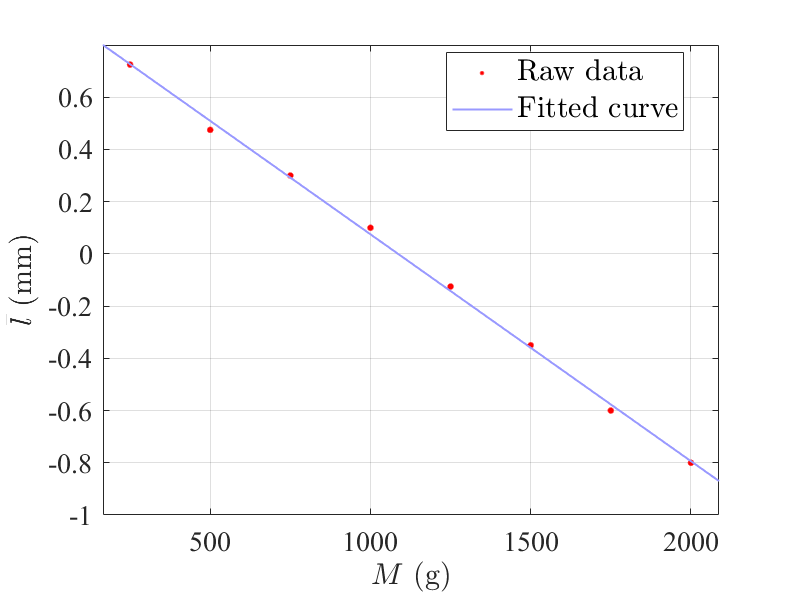


stc = MyFitPlot(fit, M', l_bar');
stc.label.x.String = '$M$ (g)';
stc.label.y.String = '$\bar{l}$ (mm)';
ylim([-1 0.8])

%MyExport_pdf_docked

## 霍尔法 (黄铜数据)

clc, clear, close all

g = 9.807

g = 9.8070


% 黄铜
size = [
229.2	230.1	230.0	229.4	229.3	229.3
23.50	23.46	23.44	23.44	23.48	23.52
0.980	0.983	0.979	0.965	0.980	0.986    
];
mean_size = mean(size, 2)

mean_size =   229.5500
   23.4733
    0.9788


data = [
12.4	22.0	29.6	39.8	50.0	59.5	70.3	80.0
1.125	1.229	1.316	1.433	1.540	1.659	1.782	1.897
34	58	78	104	128	149	175	201    
];
mean(data, 2)

ans =    45.4500
    1.4976
  115.8750



u_A = sqrt( sum( ( size-mean_size ).^2, 2 ) / (6*5) )

u_A =     0.1607
    0.0133
    0.0030


u_B2 = [0.12; 0.02; 0.004]/sqrt(3)

u_B2 =     0.0693
    0.0115
    0.0023


u = sqrt(u_A.^2 + u_B2.^2)

u =     0.1750
    0.0176
    0.0038



Delta_Z = data(2, 5:8) - data(2, 1:4)

Delta_Z =     0.4150    0.4300    0.4660    0.4640


mean_Delta_Z = mean(Delta_Z)

mean_Delta_Z = 0.4438

u_Delta_Z = u2(Delta_Z, 4, 0.002)

u_Delta_Z = 0.0127


Delta_M = data(1, 5:8) - data(1, 1:4)

Delta_M =    37.6000   37.5000   40.7000   40.2000


mean_Delta_M = mean(Delta_M)

mean_Delta_M = 39

u_Delta_M = u2(Delta_M, 4, 0.1)

u_Delta_M = 0.8456

## 霍尔法 (铸铁数据)

disp('------------- 下面是铸铁 -------------')

------------- 下面是铸铁 -------------



clc, clear, close all

g = 9.807

g = 9.8070


% 铸铁
size = [
229.4	230.0	229.5	229.5	229.8	230.1
23.32	23.34	23.36	23.34	23.341	23.32
0.973	0.976	0.969	0.974	0.973	0.975
];
mean_size = mean(size, 2)

mean_size =   229.7167
   23.3368
    0.9733


data = [
20.2	39.6	60.0	81.4	100.6	120.5	140.0	160.0
0.189	0.320	0.461	0.603	0.717	0.868	1.019	1.162
31	61	91	122	150	178	205	233 
];
mean(data, 2)

ans =    90.2875
    0.6674
  133.8750



u_A = sqrt( sum( ( size-mean_size ).^2, 2 ) / (6*5) )

u_A =     0.1195
    0.0062
    0.0010


u_B2 = [0.12; 0.02; 0.004]/sqrt(3)

u_B2 =     0.0693
    0.0115
    0.0023


u = sqrt(u_A.^2 + u_B2.^2)

u =     0.1381
    0.0131
    0.0025



Delta_Z = data(2, 5:8) - data(2, 1:4)

Delta_Z =     0.5280    0.5480    0.5580    0.5590


mean_Delta_Z = mean(Delta_Z )

mean_Delta_Z = 0.5482

u_Delta_Z = u2(Delta_Z, 4, 0.002)

u_Delta_Z = 0.0073


Delta_M = data(1, 5:8) - data(1, 1:4)

Delta_M =    80.4000   80.9000   80.0000   78.6000


mean_Delta_M = mean(Delta_M)

mean_Delta_M = 79.9750

u_Delta_M = u2(Delta_M, 4, 0.1)

u_Delta_M = 0.4973

## 霍尔法 (结果计算)

% 黄铜或铸铁
d = mean_size(1)*10^(-3)

d = 0.2297

b = mean_size(2)*10^(-3)

b = 0.0233

a = mean_size(3)*10^(-3)

a = 9.7333e-04

Delta_M = mean_Delta_M*10^(-3);
Delta_Z = mean_Delta_Z*10^(-3);
mean_Y = d^3*Delta_M*g / (4*a^3*b*Delta_Z)

mean_Y = 2.0147e+11


u_d = u(1)*10^(-3)

u_d = 1.3812e-04

u_b = u(2)*10^(-3)

u_b = 1.3090e-05

u_a = u(3)*10^(-3)

u_a = 2.5122e-06

u_Delta_Z = u_Delta_Z*10^(-3)

u_Delta_Z = 7.2844e-15

u_Delta_M = u_Delta_M*10^(-3)

u_Delta_M = 5.0724e-13

u_Y = mean_Y * sqrt( ...
    (3*u_d/d)^2 + (u_Delta_M/Delta_M)^2 + (3*u_a/a)^2 + (u_b/b)^2 + (u_Delta_Z/Delta_Z)^2 ...
)

u_Y = 1.6057e+09


disp(['Y = ', num2str(mean_Y, '%.3e'), ' +- ', num2str(u_Y, '%.3e')])

Y = 2.015e+11 +- 1.606e+09



Y_0 = 10.55e10

Y_0 = 1.0550e+11

eta = (mean_Y - Y_0)/Y_0*100

eta = 90.9634



Y_0 = 18.15e10

Y_0 = 1.8150e+11

eta = (mean_Y - Y_0)/Y_0*100

eta = 11.0008


% 最小二乘
U = data(3, :);
Z = data(2, :);
k = sum( (U - mean(U)).*(Z - mean(Z)) ) / sum( (Z - mean(Z)).^2 )

k = 207.9053


% 作图法
[fit, ou] = Fit_linear(Z, U)

fit =      线性模型 Poly1:
     fit(x) = p1*x + p2
     系数(置信边界为 95%):
       p1 =       207.9  (197.3, 218.5)
       p2 =      -4.936  (-12.76, 2.885)

ou = 包含以下字段的 struct :
           sse: 90.5856
       rsquare: 0.9974
           dfe: 6
    adjrsquare: 0.9970
          rmse: 3.8856


h = 1e-8

h = 1.0000e-08

k = (fit(1.5 + h) - fit(1.5))/h

k = 207.9050

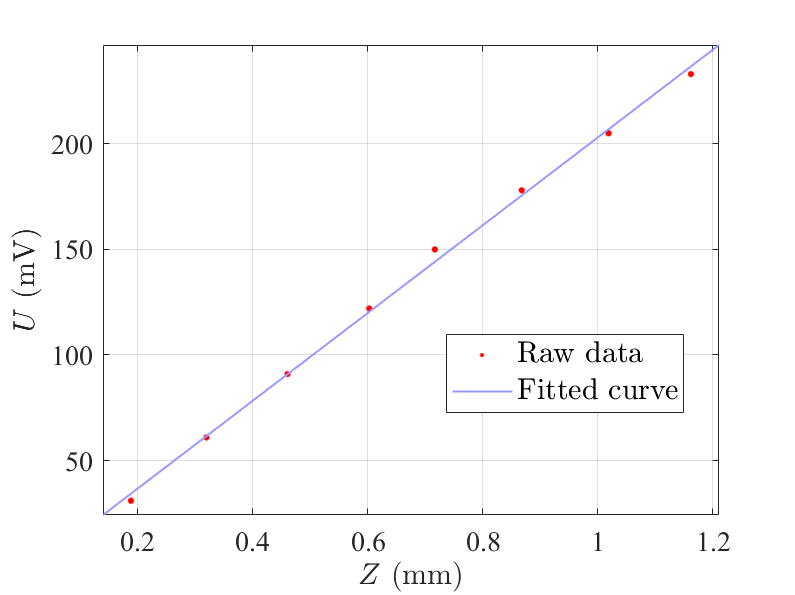



stc = MyFitPlot(fit, Z, U);
stc.label.x.String = '$Z$ (mm)';
stc.label.y.String = '$U$ (mV)';
%MyExport_pdf

## 动态法

u_L = u1_2length(1, 0.12)   %% 单位 mm

u_L = 0.1575

u_d = u1_2length(0.01, 0.004)   %% 单位 mm

u_d = 0.0027

u_M = u1_2length(0.01, 0.01)   %% 单位 g

u_M = 0.0059



L = 180.0

L = 180

X = [20	25	30	35	45	50	55	60]

X =     20    25    30    35    45    50    55    60


xL = X/L

xL =     0.1111    0.1389    0.1667    0.1944    0.2500    0.2778    0.3056    0.3333


f = [592.696	589.847	588.386	587.325	586.789	587.759	588.798	590.082]

f =   592.6960  589.8470  588.3860  587.3250  586.7890  587.7590  588.7980  590.0820


[fit, ou] = Fit_deg4(xL, f)

fit =      线性模型 Poly4:
     fit(x) = p1*x^4 + p2*x^3 + p3*x^2 + p4*x + p5
     系数(置信边界为 95%):
       p1 =      -228.8  (-1.776e+04, 1.731e+04)
       p2 =      -435.5  (-1.605e+04, 1.518e+04)
       p3 =       729.3  (-4267, 5725)
       p4 =        -253  (-930.1, 424.1)
       p5 =       612.4  (579.7, 645)

ou = 包含以下字段的 struct :
           sse: 0.1487
       rsquare: 0.9941
           dfe: 3
    adjrsquare: 0.9862
          rmse: 0.2226


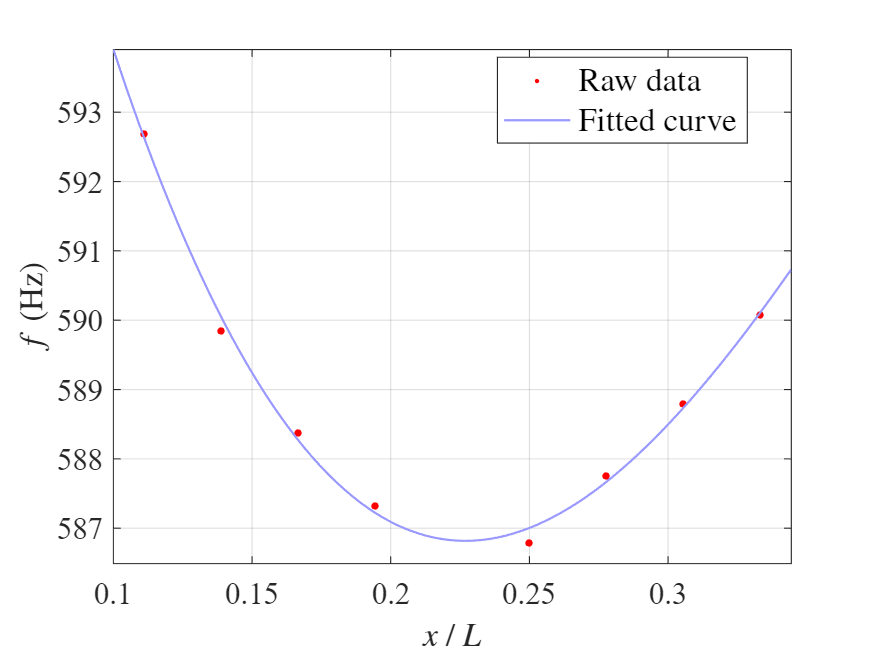

stc = MyFitPlot(fit, xL, f);
stc.ax.YLim = [stc.ax.YLim(1) - 0.3, stc.ax.YLim(2)];
stc.label.x.String = '$x\: /\, L$';
stc.label.y.String = '$f$ (Hz)';

%MyExport_pdf_docked
h = 10^(-6)

h = 1.0000e-06

df = @(x) (fit(x + h) - fit(x))/h

df = 包含以下值的 function_handle :
    @(x)(fit(x+h)-fit(x))/h


x = fzero(df, 0.25)

x = 0.2269

vpa(x)

$$ans = 0.22688279067129493715704313672177$$

f_1 = fit(x)

f_1 = 586.8180



m = 42.1e-3

m = 0.0421

L = 180e-3

L = 0.1800

d = 5.956e-3

d = 0.0060

u_M = u_M*10^(-3);
u_L = u_L*10^(-3);
u_d = u_d*10^(-3);
mean_Y = 1.6067*  L^3*m*f_1^2 / d^4

mean_Y = 1.0795e+11

u_Y = mean_Y * sqrt( ...
     (3*u_L/L)^2 + (u_M/m)^2 + (4*u_d/d)^2   ...
)

u_Y = 3.4504e+08

function stc = MyFitPlot(fit, X, Y)
    stc.fig = figure('Color', [1 1 1]);
    stc.ax = axes('Parent',stc.fig, 'FontSize', 14); 
    stc.sca = MyScatter_ax(stc.ax, X, Y);
    stc.sca.scatter.scatter_1.SizeData = 100;
    stc.sca.scatter.scatter_1.MarkerEdgeColor = 'r';
    
    x_ra = (max(X) - min(X));
    x_array = linspace(min(X) - 0.05*x_ra, max(X) + 0.05*x_ra, 300);
    stc.pl = MyPlot_ax(stc.ax, x_array, fit(x_array)');
    stc.pl.plot.plot_1.LineWidth = 1;

    % 坐标轴
        stc.ax.FontName = "Times New Roman"; % 全局 FontName
        stc.ax.XGrid = 'on';
        stc.ax.YGrid = 'on';
        %stc_MyYYPlot.axes.GridLineStyle = '--';
        stc.ax.XLimitMethod = 'tight';
        stc.ax.YLimitMethod = 'tight';
        stc.ax.Box = 'on';  
        stc.label.x = xlabel(stc.ax, '$x$', 'Interpreter', 'latex', 'FontSize', 15);
        stc.label.y = ylabel(stc.ax, '$y$', 'Interpreter', 'latex', 'FontSize', 15);

    % 标题
        %stc.ax.Title.String = 'Figure: MyPlot';
        stc.ax.Title.FontSize = 17;
        stc.ax.Title.FontWeight = 'bold';

    % 图例
        stc.leg = legend(stc.ax, 'Location', 'best');
        stc.leg.FontSize = 15;
        stc.leg.Interpreter = "latex";
        stc.leg.String = ["Raw data"; "Fitted curve"];
end

function re = u2(X, n, e)
    u_A = sqrt( sum( ( X-mean(X, 2) ).^2, 2 ) / (n*(n-1)) );
    u_B2 = e/sqrt(3);
    re = sqrt(u_A.^2 + u_B2.^2);
end

function re = u1_2length(d, e)
    u_B1 = d/10;
    u_B2 = e/sqrt(3);
    re = sqrt(2*u_B1.^2 + u_B2.^2);
end